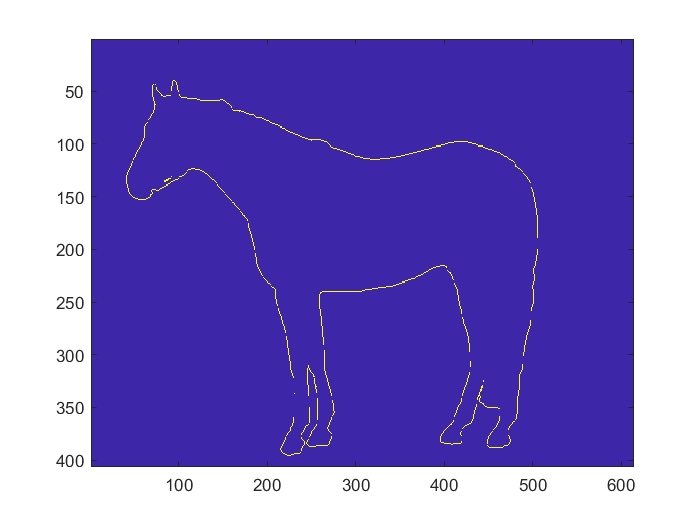

outline = zeros([s1,s2]);

for i = 2:s1-1
    for j = 2:s2-1
        Area(i,j);
        cluster = Area(i-1:i+1,j-1:j+1);
        
        if sum(sum(cluster)) >1 
            outline(i,j) = 1;
            
        end
        
    end
end

outline = outline-Area;               % reverse engineer the outline
[x1,y1] = find(outline == 1);
bc = [x1,y1];                         % coordinates of points on the outline

imagesc(outline)